# Topological Clustering

This example shows how various topological clustering methods are performed in well constrcuted toy examples with the ground truth. The simultation study is published in Chung, M. K., Huang, S. G., Carroll, I. C., Calhoun, V. D., & Goldsmith, H. H. (2024). [Topological state-space estimation of functional human brain networks](https://journals.plos.org/ploscompbiol/article/file?id=10.1371/journal.pcbi.1011869&type=printable). *PLOS Computational Biology*, *20*(5), e1011869. 

The **bottleneck distance** and **Wassersetin distance** between graph filtrations is explained in Chung, M.K., Ramos, C.G., De Paiva, F.B., Mathis, J., Prabhakaran, V., Nair, V.A., Meyerand, M.E., Hermann, B.P., Binder, J.R. and Struck, A.F. 2023 [Unified Topological Inference for Brain Networks in Temporal Lobe Epilepsy Using the Wasserstein Distance](https://arxiv.org/pdf/2302.06673), NeuroImage 15:120436. The **hierarchical clustering** is based on the Gromov-Hausdorff (GH) distance introduced in Lee, H., Chung, M.K., Kang, H., Kim, B.N. and Lee, D.S., 2011, [Computing the shape of brain networks using graph filtration and Gromov-Hausdorff metric](https://brainimaging.waisman.wisc.edu/~chung/DTI/literature/lee.2011.MICCAI.pdf). In MICCAI (pp. 302-309). **k-means clustering** and its topological version (using Wassertein distance) is explained in Chung, M. K., Huang, S. G., Carroll, I. C., Calhoun, V. D., & Goldsmith, H. H. (2024). [Topological state-space estimation of functional human brain networks](https://journals.plos.org/ploscompbiol/article/file?id=10.1371/journal.pcbi.1011869&type=printable). *PLOS Computational Biology*, *20*(5), e1011869. If you are using any part of codes or simulation data below, reference [Chung et al. (2023)](https://arxiv.org/pdf/2302.06673) or other above papers. 

(C) 2021- Moo K. Chung, Univeristy of Wisconsin-Madison

The exaple codes are modified from the original codes from [https://github.com/laplcebeltrami/dynamicTDA.](https://github.com/laplcebeltrami/dynamicTDA.) Update history: 2021 December 22 created; 2023 March 26 WS_cluster.m added; 2025 january 30 Repackaged for BMI768 class; 2026 Mar 10 Made into mlx. 

## Ground truth for testing false negatives

The simulation generates known topological differences between groups. This provides a reference truth that allows evaluation of the method’s ability to detect true effects and quantify false negatives. The simulation setting for testing false positives are left as an exercise. 

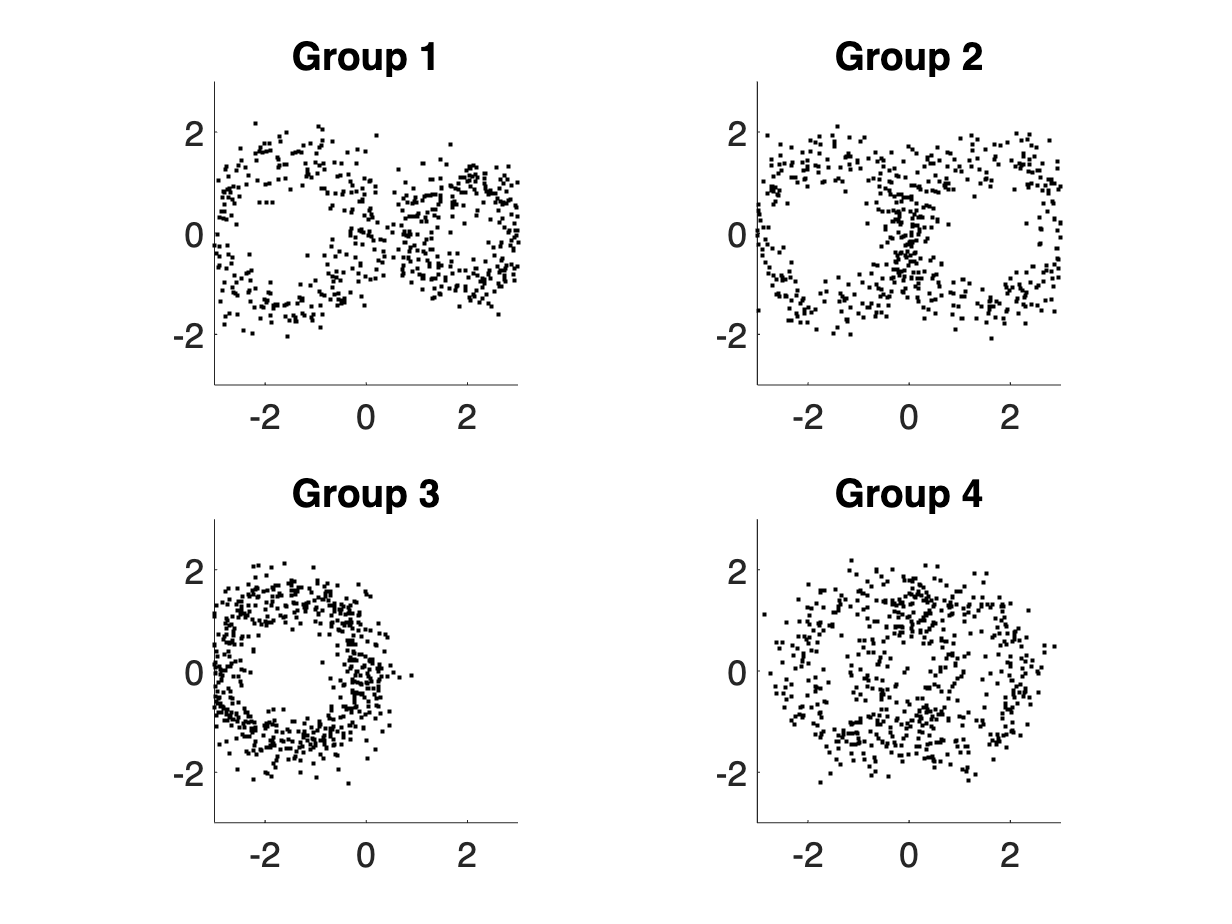

sigma=0.3;   %amount of noise
npoints=60; %# of random scatter points along circles
nSubjects = 5; % # of subjects in each group
coord_d=simulate_circle_difference(sigma, npoints, nSubjects);  
plot_clusters_coords(coord_d); %Visualizing networks

## Ground truth for testing false positives

The simulation generates datasets in which the groups have identical topological structure. Under this setting, any detected difference arises purely from random variation. This provides a reference framework for evaluating the method’s ability to control false positives by measuring how often it *incorrectly* detects a topological difference when none exists.

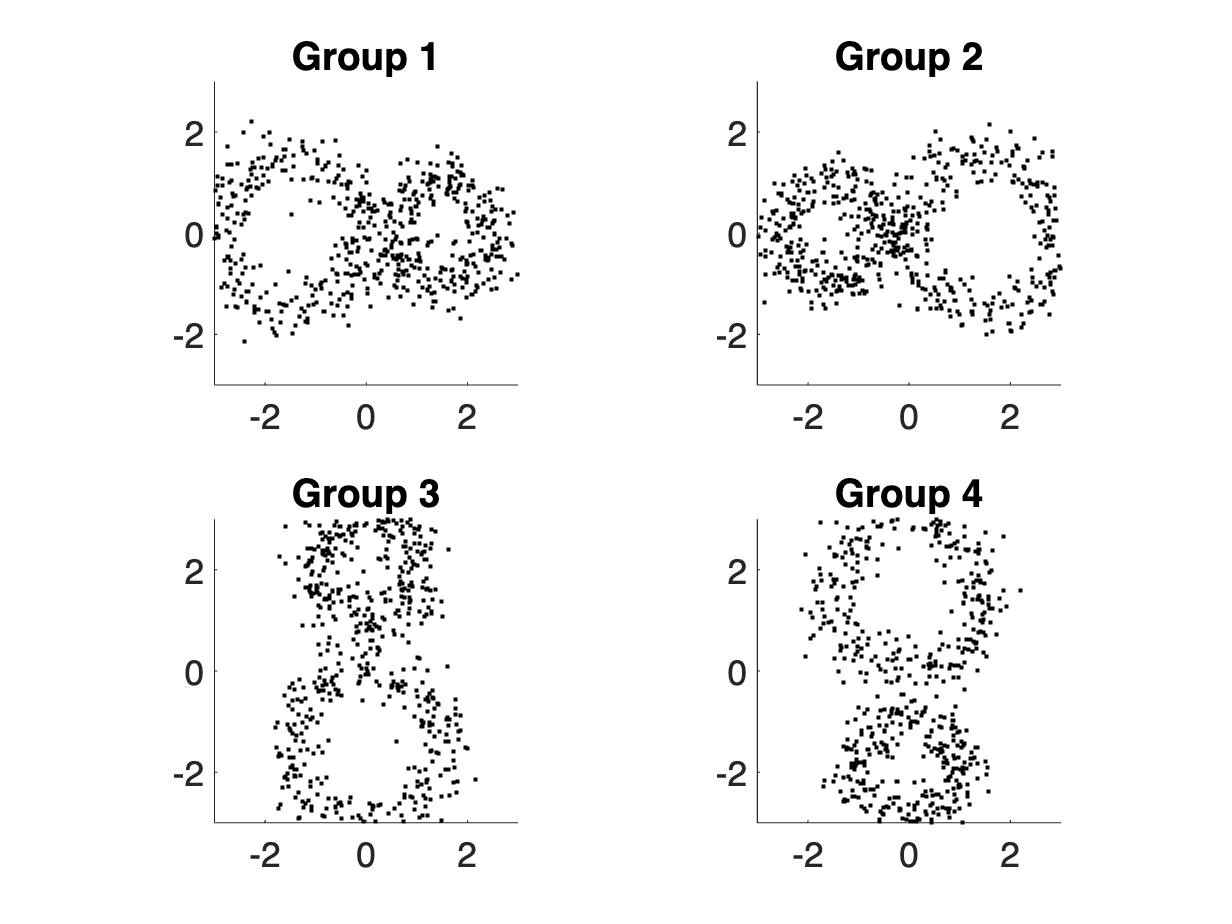

coord_e=simulate_circle_equal(sigma, npoints,nSubjects);  
plot_clusters_coords(coord_e);

## Clustering comparisons

This simulation exactly follow the simulation study published in [Chung et al. (2024)](https://journals.plos.org/ploscompbiol/article?id=10.1371/journal.pcbi.1011869). Due to random sampling, the numerical results will vary slightly across different simulations.

nSim = 10; %Publication above all used 100 simulations
perf = clustering_comparions(nSim, sigma, npoints, nSubjects, 'equal'); %equal topology

Performance summary (mean ± std)
K-means           : 0.861 ± 0.014
Bottleneck-0      : 0.530 ± 0.048
Bottleneck-1      : 0.615 ± 0.082
Gromov-Hausdorff  : 1.000 ± 0.000
Wasserstein       : 0.574 ± 0.041


When the simulated groups share identical topology, the clustering methods should ideally fail to separate them because no true structural difference exists. In this setting, topology-based distances generally produce clustering performance close to random assignment, reflecting the absence of a meaningful topological signal distinguishing the groups. This behavior is desirable because it indicates that these methods do not artificially create differences when the underlying topology is the same.

In contrast, clustering approaches that rely on geometric or Euclidean representations may still appear to separate the groups even though their topology is identical. Such separation arises from incidental geometric variations in the simulated data rather than genuine topological differences. This illustrates an important principle of topological data analysis: methods designed to capture topological structure remain stable when topology is preserved, whereas purely geometric methods may detect spurious group differences driven by noise or sampling variability.

perf = clustering_comparions(nSim, sigma, npoints, nSubjects, 'different'); %different topology

Performance summary (mean ± std)
K-means           : 0.826 ± 0.020
Bottleneck-0      : 0.815 ± 0.078
Bottleneck-1      : 0.845 ± 0.121
Gromov-Hausdorff  : 1.000 ± 0.000
Wasserstein       : 0.952 ± 0.018


The results indicate that clustering methods based on topological distances are able to detect structural differences between the simulated groups. In contrast, clustering methods that operate directly on Euclidean representations (k-means) or partial topological summaries (Bottleneck-0 or Bottleneck-1) can exhibit greater variability across simulations. These approaches may still detect the group differences, but their performance is more sensitive to noise and to variations in the simulated geometry. 

#### **Problems**

Based on the performance in the false negative and false positive experiments, how should the two types of errors be combined into a single evaluation criterion? Propose a principled summary measure that balances sensitivity to true topological differences against robustness to spurious detections, and explain why your choice is appropriate for comparing clustering methods.